Matlab project :)

**Specific requirements:**

- Introduce the source, format, and background of the data set, what kind of statistical/machine learning task(s) it is originally created for, and websites, papers, or competitions that use the data set.

- Report summary information of the data set, such as #instances, #features (categorical, or numerical), % missing values (if any).

- Visualization of single or small subsets of variables. 

                - Visualization based on 1 - 3 variables at a time should still be performed:

                        - Single categorical variable(s)

                        - General numerical data 

                        - Selected single numerical variables

                        - Selected pairs of variables (both numerical, one numerical + one categorical)

                        - Selected triples of variables (all numerical, two numerical + one categorical)

                        - (if we add reviews) Documents data (refer to data_plotting4.m)

- Feature scaling (if the magnitudes of the variables are very different, normalize them to a common range such as [0,1], or [-1,1])

- Dimension reduction methods to be applied to the data set (for simultaneous visualization of all the numerical variables):  

- Linear, unsupervised: PCA

- Linear, supervised: LDA

- Nonlinear, unsupervised, global: MDS (with any metric except Euclidean) 

- Nonlinear, unsupervised, local: Laplacian Eigenmaps, or another nonlinear one (such as LLE). In the latter case, you must provide a brief, clear description of the algorithm regarding how it works.

Project Steps:

- clean the data

- summary statistics, and visualization of single or small subsets of variables. 

- put all numerical data in a matrix and perform feature scaling

- dimension reduction methods

## **Loading the Data**

clear;
opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["App", "Category", "Rating", "Reviews", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "LastUpdated", "CurrentVer", "AndroidVer"];
opts.VariableTypes = ["string", "categorical", "double", "double", "string", "string", "categorical", "string", "categorical", "categorical", "datetime", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["App", "Size", "Installs", "Price", "CurrentVer", "AndroidVer"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["App", "Category", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "CurrentVer", "AndroidVer"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "LastUpdated", "InputFormat", "MMMM d, yyyy");
opts = setvaropts(opts, ["Rating", "Reviews"], "ThousandsSeparator", ",");

% Import the data
data = readtable("data/googleplaystore.csv", opts);
clear opts % clear temporary variables

## **Cleaning the data**

Removing Missing Variables

size(data) % 13 vairables, 10841 apps

ans =        10841          13


Missing data by variable

app = sum(ismissing(data.App));
category = sum(ismissing(data.Category));
rating = sum(ismissing(data.Rating));
reviews = sum(ismissing(data.Reviews));
Size = sum(ismissing(data.Size));
installs = sum(ismissing(data.Installs));
type = sum(ismissing(data.Type));
price = sum(ismissing(data.Price));
contentRating = sum(ismissing(data.ContentRating));
genres = sum(ismissing(data.Genres));
lastUpdated = sum(ismissing(data.LastUpdated));
currentVer = sum(ismissing(data.CurrentVer));
androidVer = sum(ismissing(data.AndroidVer));
table(app, category, rating, reviews, Size, installs, type, price, ...
    contentRating, genres, lastUpdated, currentVer, androidVer)

ans = 1×13 table
    app    category    rating    reviews    Size    installs    type    price    contentRating    genres    lastUpdated    currentVer    androidVer
    ___    ________    ______    _______    ____    ________    ____    _____    _____________    ______    ___________    __________    __________

     0        0         1474        1        0         0         0        0            1            0            1             0             1     


clear Size installs price app rating category reviews type contentRating genres lastUpdated currentVer androidVer;
data( any(ismissing(data),2), :) = [];
size(data)

ans =         9366          13


data(find(string(data.Size)=='Varies with device'),:) = []; % removing weird size
size(data) % size after deleting a ton of variables.

ans =         7729          13


Fixing data types and removing special characters

% data.Sizes
charSize = strtrim(data.Size);
msize = charSize(endsWith(charSize,'M'));
charSize_m = cellstr(string(str2double(string(strrep(msize,'M', '')))*1000));
charSize(endsWith(charSize,'M')) = charSize_m;
SizeOnlyk = strrep(charSize,'k', '');
data.Size_K = SizeOnlyk;
data.Size_K = str2double(string(data.Size_K));

% data.Installs
data.Installs = str2double(strrep(data.Installs,'+',''));

% data.Price
data.Price = str2double(strrep(data.Price,'$',''));

% cleaning up
clear charSize charSize_m msize SizeOnlyk;

Visualization plan

Summary statistics: (top 5 we create plots for)

- maximum price (top 5)

- average price of paid games

- maximum installs (top 5)

- average installs

- average size

- average rating

- top 5 ratings

- average reviews

- top 5 reviews

single categorical variable: (tien) + summary statistics

- category

- type

- content rating

- genre

single numerical variables: (shayna) + summary statistics

- rating

- reviews

- size

- price

- installs

Single Numerical Variables

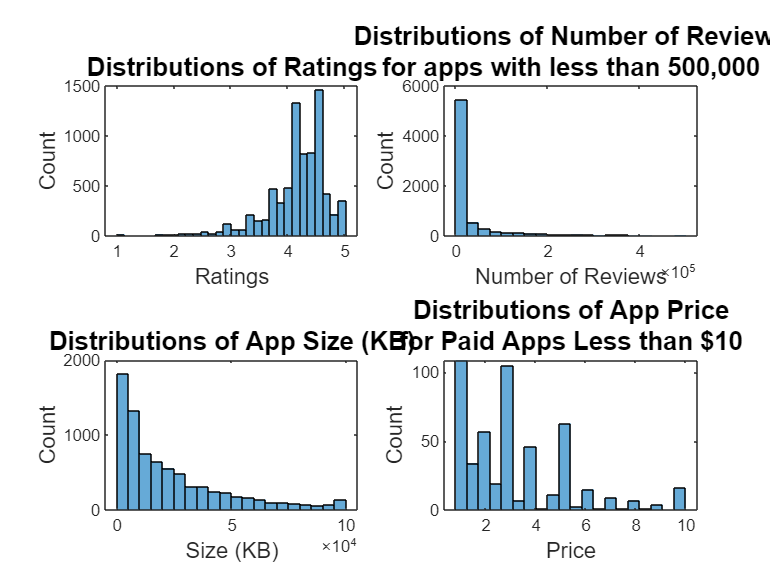

figure;
% Ratings plot
subplot(2,2,1)
histogram(data.Rating,30)
title("Distributions of Ratings",FontSize=14)
xlabel("Ratings",FontSize=12)
ylabel("Count",FontSize=12)

% Reviews plot probably not going to include
subplot(2,2,2)
histogram(data.Reviews(find(data.Reviews<500000)),20)
title({"Distributions of Number of Reviews", "for apps with less than 500,000"},FontSize=14)
xlabel("Number of Reviews",FontSize=12)
ylabel("Count",FontSize=12)

% Size plot
subplot(2,2,3)
histogram(data.Size_K,20)
title("Distributions of App Size (KB)",FontSize=14)
xlabel("Size (KB)",FontSize=12)
ylabel("Count",FontSize=12)

% Price plot
subplot(2,2,4)
histogram(data.Price(find(data.Price < 10 & data.Price > 0)),20)
title({"Distributions of App Price", "for Paid Apps Less than $10"},FontSize=14)
xlabel("Price",FontSize=12)
ylabel("Count",FontSize=12)

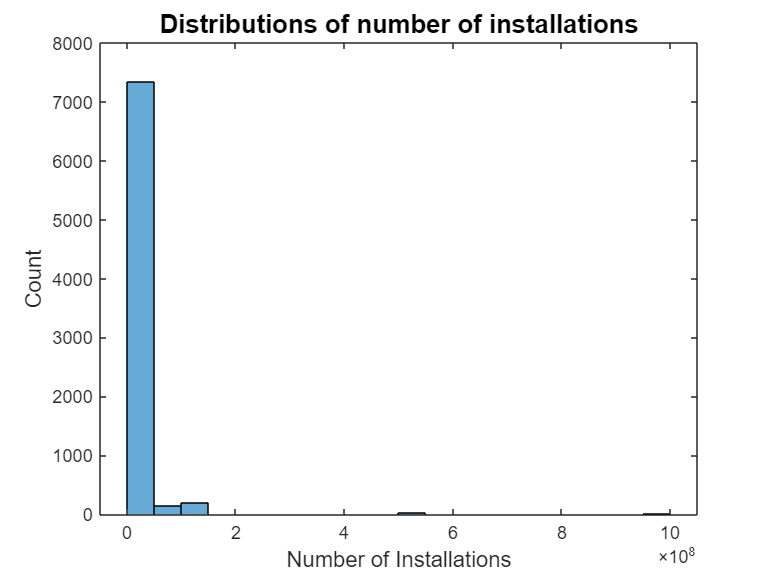



% % Most frequent prices
% [n,bin] = hist(data.Price,unique(data.Price));
% [~,idx] = sort(-n);
% n(idx) % The counts
% 
% bin(idx) % the prices

% installs plot is not good maybe we don't include it
figure;
histogram(data.Installs,20) % trying different things
title("Distributions of number of installations",FontSize=14)
xlabel("Number of Installations",FontSize=12)
ylabel("Count",FontSize=12)

Selected pairs of variables both numerical (tien)

Selected pairs of variables one numerical + one categorical (shayna)

(N,C): (rating, category) (rating, type) (rating, content rating) (rating, genre), *Review data was so heavily skewed the graphs look bad so I am skipping it!, (Size, category) (Size, type) (Size, content rating) (Size, genre), (price, category) (price, content rating) (price, genre), *Also skipped installs for the same reason

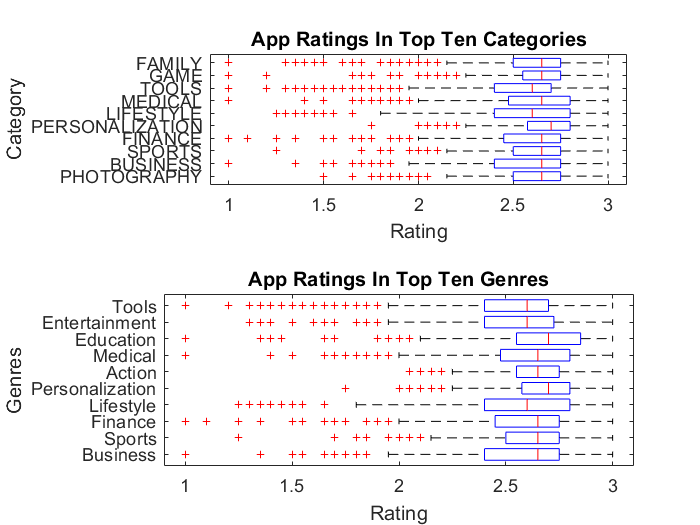

% Most popular cateogires
[n,bin] = hist(data.Category,unique(data.Category));
[~,idx] = sort(-n);
catCounts = n(idx); % The counts for each category sorted
catOrder = bin(idx); % Thier corresponding category sorted
data.Category = categorical(data.Category,catOrder); % categories will be in order of more popular in graph
dataTopCat = data(find(data.Category == catOrder(1) | data.Category == catOrder(2) ...
    | data.Category == catOrder(3) | data.Category == catOrder(4) ...
    | data.Category == catOrder(5) | data.Category == catOrder(6) ...
    | data.Category == catOrder(7) | data.Category == catOrder(8) ...
    | data.Category == catOrder(9) | data.Category == catOrder(10)),:);

% Most popular Genres
[n,bin] = hist(data.Genres,unique(data.Genres));
[~,idx] = sort(-n);
genreCounts = n(idx); % The counts for each category sorted
genreOrder = bin(idx); % Thier corresponding category sorted
data.Genres = categorical(data.Genres,genreOrder); % genres will be in order of more popular in graph
dataTopGenre = data(find(data.Genres == genreOrder(1) | data.Genres == genreOrder(2) ...
    | data.Genres == genreOrder(3) | data.Genres == genreOrder(4) ...
    | data.Genres == genreOrder(5) | data.Genres == genreOrder(6) ...
    | data.Genres == genreOrder(7) | data.Genres == genreOrder(8) ...
    | data.Genres == genreOrder(9) | data.Genres == genreOrder(10)),:);

figure;
% Rating v Categories
subplot(2,1,1);
boxplot(dataTopCat.Rating,dataTopCat.Category,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"App Ratings In Top Ten Categories"},FontSize=16)
ylabel("Category",FontSize=12)
xlabel("Rating",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

% Rating v Genres
subplot(2,1,2); 
boxplot(dataTopGenre.Rating,dataTopGenre.Genres,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"App Ratings In Top Ten Genres"},FontSize=16)
ylabel("Genres",FontSize=12)
xlabel("Rating",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

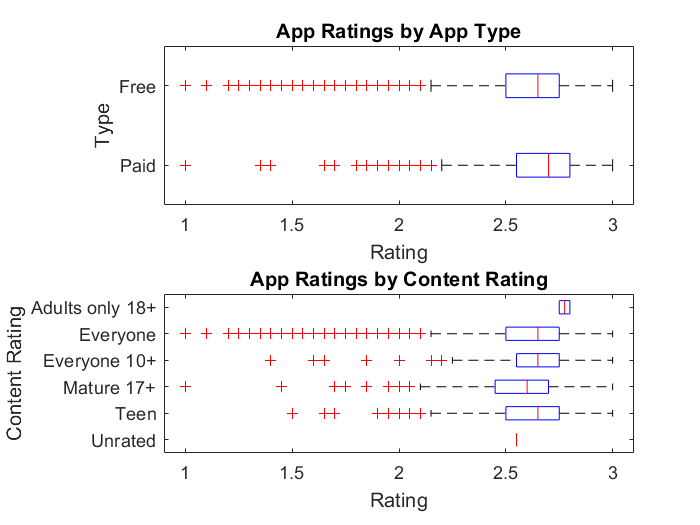

figure;
% Rating v Type
subplot(2,1,1); 
boxplot(data.Rating,data.Type,'Orientation','horizontal')
title({"App Ratings by App Type"},FontSize=14)
ylabel("Type",FontSize=12)
xlabel("Rating",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

% Rating v Content Rating
subplot(2,1,2); 
boxplot(data.Rating,data.ContentRating,'Notch','off','Orientation','horizontal')
title({"App Ratings by Content Rating"},FontSize=14)
ylabel("Content Rating",FontSize=12)
xlabel("Rating",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

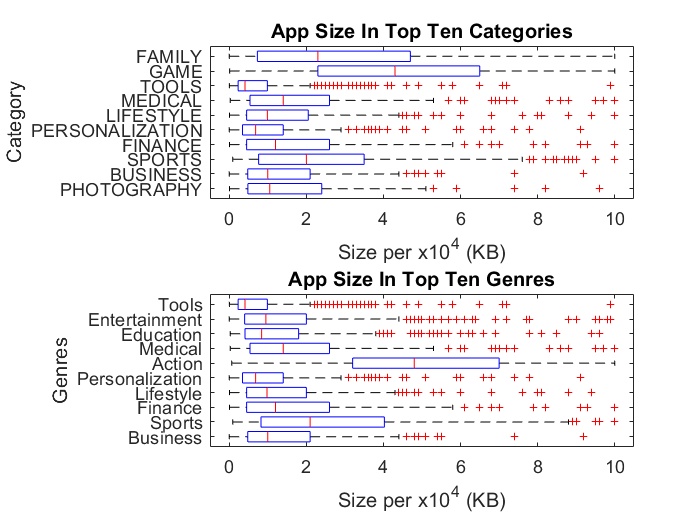

figure;
% Size v Categories
subplot(2,1,1);
boxplot(dataTopCat.Size_K,dataTopCat.Category,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"App Size In Top Ten Categories"},FontSize=16)
ylabel("Category",FontSize=12)
xlabel("Size per x10^4 (KB)",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

% Size v Genres
subplot(2,1,2); 
boxplot(dataTopGenre.Size_K,dataTopGenre.Genres,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"App Size In Top Ten Genres"},FontSize=16)
ylabel("Genres",FontSize=12)
xlabel("Size per x10^4 (KB)",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

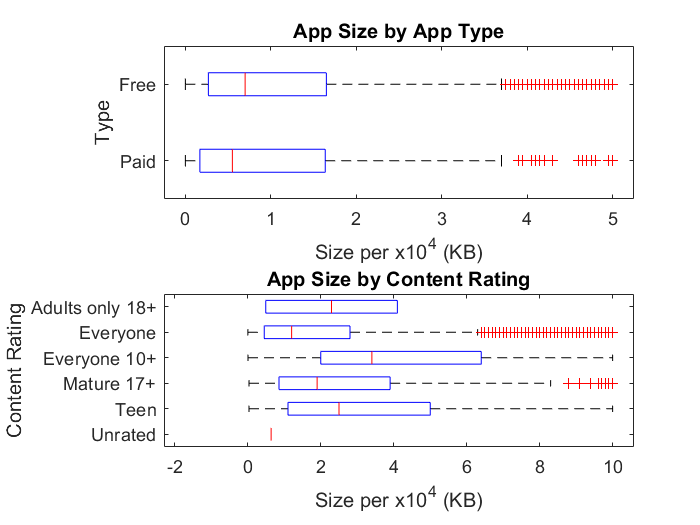

figure;
% Size v Type
subplot(2,1,1); 
boxplot(data.Size_K,data.Type,'Orientation','horizontal')
title({"App Size by App Type"},FontSize=14)
ylabel("Type",FontSize=12)
xlabel("Size per x10^4 (KB)",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

% Size v Content Rating
% idk why this one has negative values.
% min(data.Size_K)
subplot(2,1,2); 
boxplot(data.Size_K,data.ContentRating,'Notch','off','Orientation','horizontal')
title({"App Size by Content Rating"},FontSize=14)
ylabel("Content Rating",FontSize=12)
xlabel("Size per x10^4 (KB)",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse') 

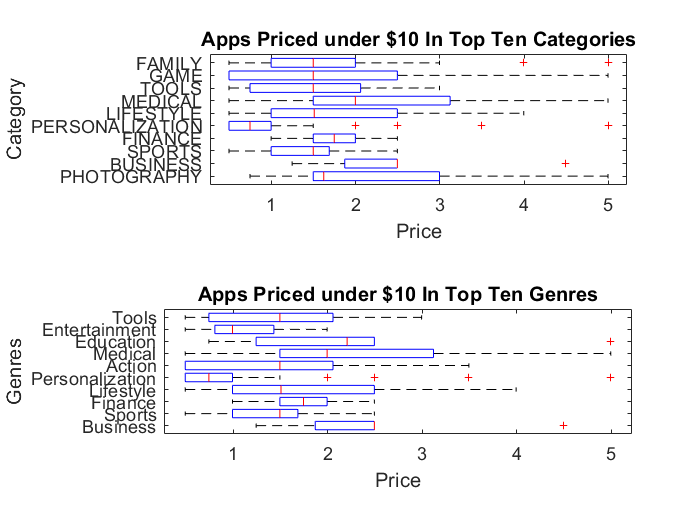

figure;
% Price v Categories
subplot(2,1,1);
boxplot(dataTopCat.Price(find(dataTopCat.Price>0 & dataTopCat.Price<10)),dataTopCat.Category(find(dataTopCat.Price>0 & dataTopCat.Price<10)),'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"Apps Priced under $10 In Top Ten Categories"},FontSize=16)
ylabel("Category",FontSize=12)
xlabel("Price",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

% Price v Genres
subplot(2,1,2); 
boxplot(dataTopGenre.Price(find(dataTopGenre.Price>0 & dataTopGenre.Price<10)),dataTopGenre.Genres(find(dataTopGenre.Price>0 & dataTopGenre.Price<10)),'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
title({"Apps Priced under $10 In Top Ten Genres"},FontSize=16)
ylabel("Genres",FontSize=12)
xlabel("Price",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

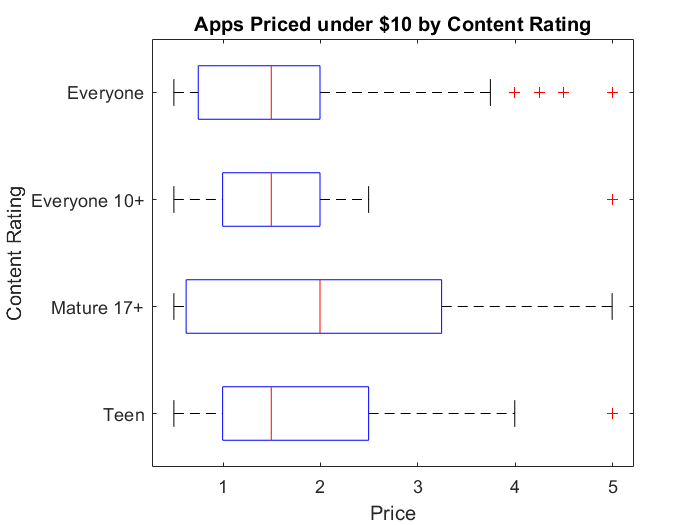


figure;
% Price v Type
boxplot(data.Price(find(data.Price>0 & data.Price<10)),data.ContentRating(find(data.Price>0 & data.Price<10)),'Notch','off','Orientation','horizontal')
title({"Apps Priced under $10 by Content Rating"},FontSize=14)
ylabel("Content Rating",FontSize=12)
xlabel("Price",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')

% cleaning up
%clear catCounts catOrder dataTopCat dataTopGenre genreCounts genreOrder

Selected triples of variables all numerical (tien)

Selected triples of variables two numerical + one categorical (shayna)

- category

- type

- content rating

- genre

- rating

- reviews

- size

- price

- installs